## Resistor-Inductor circuits

circuit = Circuit('circuits/passive/c3_rl.txt');
circuit.list

ans =     'Vin 1 0 DC 5
     R1 2 0 1000
     L1 1 2 3
     '


ELAB.analyze(circuit)

Symbolic analysis successful (0.22945 sec).


Maybe you want expressions for node voltages.

circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=\mathrm{Vin}\\ v_{2}=\frac{R_{1}\,\mathrm{Vin}}{R_{1}+L_{1}\,s} \end{array}\right)$$

Or the numerical currents for all elements in this particular circuit in relation to the s-domain.

ELAB.evaluate(circuit)


Numerical evaluation successful (0.039234 sec).


circuit.numerical_element_currents

$$ans = \left(\begin{array}{c} i_{\mathrm{R1}}=\frac{5}{3\,s+1000}\\ i_{\mathrm{L1}}=\frac{5\,s}{3\,s+1000} \end{array}\right)$$

Say we want the numerical transfer function, where the output is the voltage across the resistor.

TF = ELAB.ec2tf(circuit, 1, 2)

Transfer function object created successfully (2.707820e-02 sec).

TF =
 
    333.3
  ---------
  s + 333.3
 
Continuous-time transfer function.



Matlab can then be used to visualize the circuit behavior as with any other system. Plotting the Bode diagram, we see that this is also a low-pass-filter, like the rc-example.

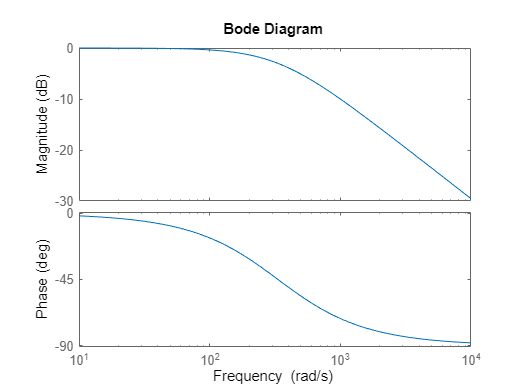

bode(TF)